%EXAMPLE IMPORT AND PLOT
record_name = '3000063';
number = '0010';

folder = record_name(1:2);

data = importdata("physionet.org/textdata/"+record_name+"_"+number+".txt")

data =          0  121.0360    0.5100
    0.0080  121.0360    0.4980
    0.0160  120.6220    0.4820
    0.0240  120.6220    0.4710
    0.0320  120.6220    0.4590
    0.0400  121.8650    0.4510
    0.0480  124.3520    0.4430
    0.0560  128.4970    0.4350
    0.0640  133.4720    0.4270
    0.0720  139.6890    0.4240


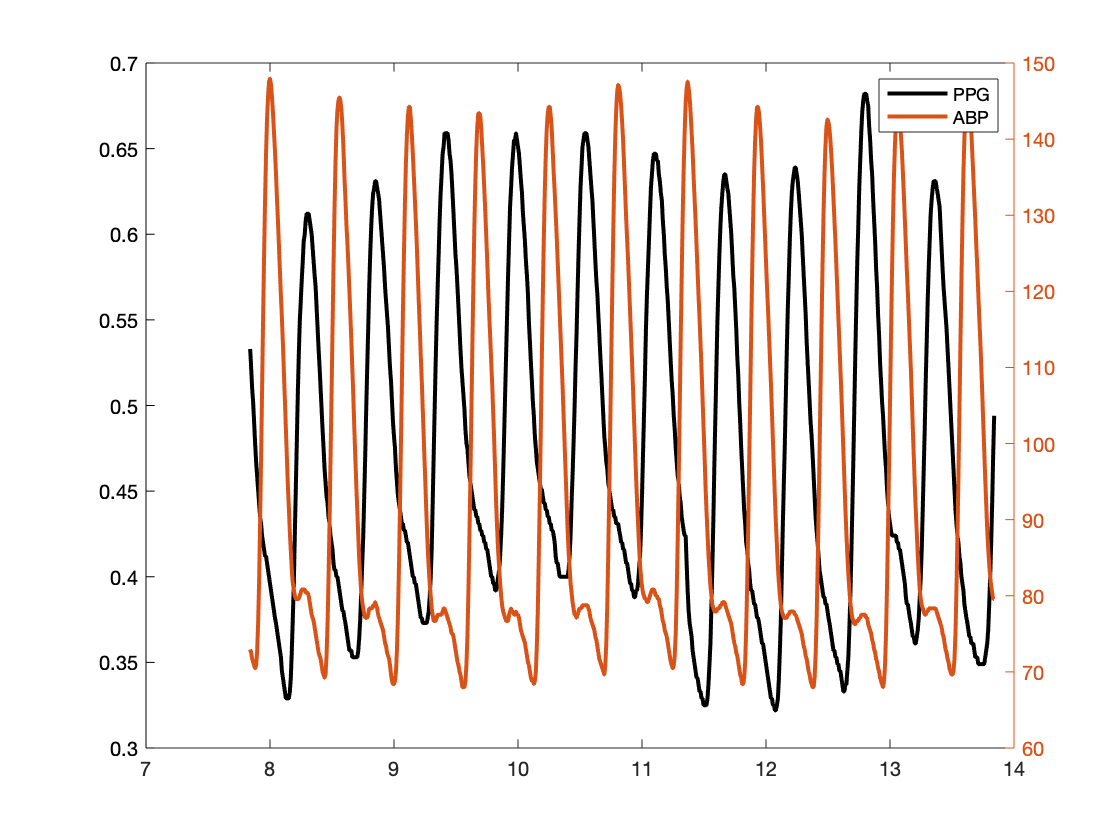


signal = data(:,2:3);
tm = data(:,1);

start_disp = round(length(tm)/4);
end_disp = start_disp+3*Fs;
clf
 plot(tm(start_disp:end_disp), signal(start_disp:end_disp,2), 'LineWidth', 2)
hold on
yyaxis right
plot(tm(start_disp:end_disp,1), signal(start_disp:end_disp,1), 'LineWidth',2)
legend("PPG", "ABP")

%FILTERING

%file size thresholding already performed in Python scraper and conversion tool

%Following MIMIC cleaning process in Slapnicar et al. Blood Pressure Estimation from Photoplethysmogram 
%       Using a Spectro-Temporal Deep Neural Network


%Get list of files 
% normalise to zero mean unit variance -> 4th order Butterworth BPF with 0.5 Hz and
% 8Hz cutoffs
orig_file_dir = "physionet.org/textdata/";
fileList = dir(orig_file_dir+"*.txt") %only consider all text files

fileList = 71×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


cleaned_file_dir = "physionet.org/cleaned_data/";
if ~isdir(cleaned_file_dir)
    mkdir(cleaned_file_dir)
end


%BPF transfer function
Fs = 250;
[bpf_num, bpf_den] = butter(2, 2*pi.*[0.25 20]/(2*pi*Fs),'bandpass')

bpf_num =     0.0131         0   -0.0261         0    0.0131


bpf_den =     1.0000   -3.6504    5.0050   -3.0586    0.7040


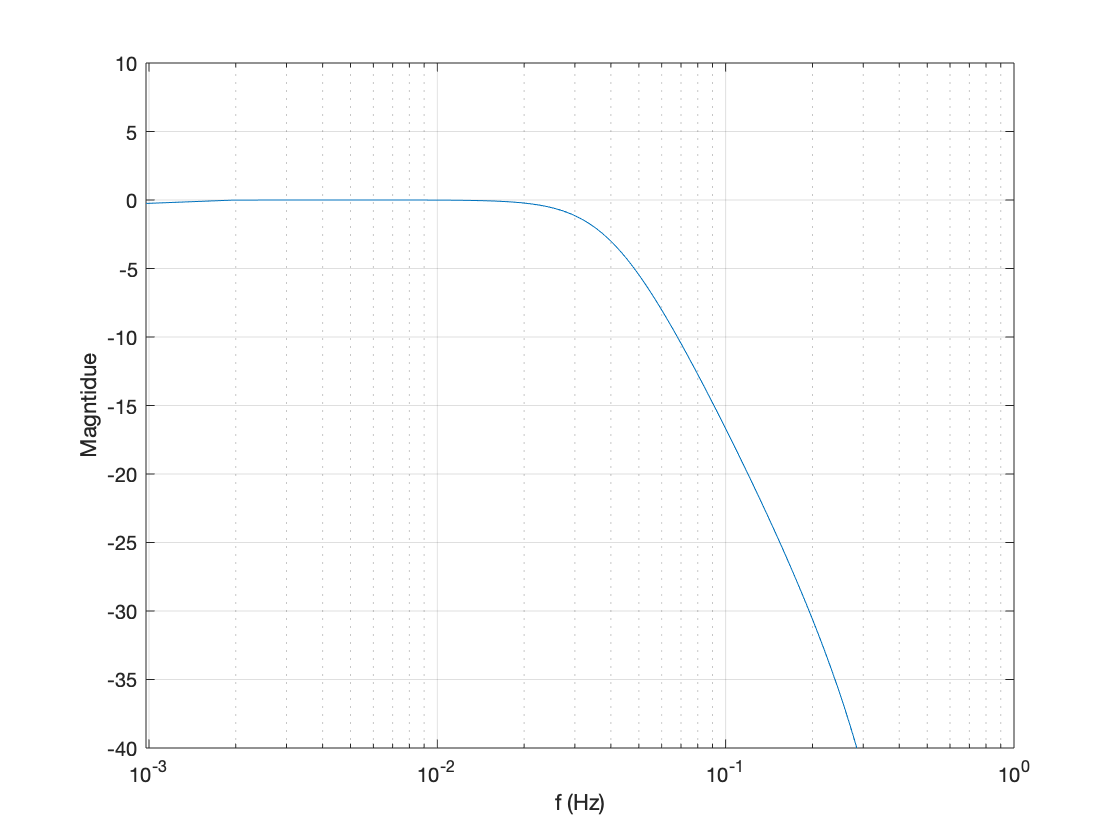

[h,w] =freqz(bpf_num, bpf_den);
clf
semilogx(w./(2*pi),20.*log10(abs(h)));
ylim([-40,10]);
grid on
xlabel('f (Hz)')
ylabel('Magntidue')




for idx = 1:length(fileList)
%      data = importdata( orig_file_dir + fileList(idx).name);
     data = cell2mat(textscan( fopen(orig_file_dir + fileList(idx).name), ...
         '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
    
     discard_file = false;
     for i=2:3
         if discard_file
             continue;
         end
         
        %to check for signal flats will use diff
        %find diff that is less than some tolerance. If multiple consecutive
        %points less than that tolerance then there is a flat
        %ISSUE: THE FLATNESS DETECTOR IS TOO SELECTIVE --  some signals
        %   have small portions that are junk but most of the long signal is
        %   fine. This signal will still be marked as junk and filtered out
        %   ex. see 3000063_0019.txt for the PLETH signal (col 3)
        tol = 1e-4;
        diff_check = (( diff(data(:,i))<tol ) & ( diff(data(:,i))>-tol )).*1;
        multiple_pts = 30;
        if( any( movmean(diff_check, multiple_pts-1)>=1) ) %use moving mean to find multiple non changing pts
            discard_file = true;
            continue;
        end
        
        data(:,i) = normalize(data(:,i));
    
        data(:,i) = filter(bpf_num, bpf_den, normalize(data(:,i)));
     end
     
     if ~discard_file
         fprintf('Writing cleaned %s to folder \n', fileList(idx).name);
         writematrix(data, cleaned_file_dir+fileList(idx).name, 'Delimiter', 'tab')
     else 
         fprintf('Marked %s as junk \n', fileList(idx).name);
     end
   

end

Marked: 0_testdata1.txt as junk 
Marked: 3000063_0006.txt as junk 
Marked: 3000063_0007.txt as junk 
Marked: 3000063_0009.txt as junk 
Marked: 3000063_0010.txt as junk 
Marked: 3000063_0011.txt as junk 
Marked: 3000063_0012.txt as junk 
Marked: 3000063_0013.txt as junk 
Marked: 3000063_0014.txt as junk 
Marked: 3000063_0015.txt as junk 
Marked: 3000063_0016.txt as junk 
Marked: 3000063_0018.txt as junk 


Writing cleaned 3000063_0019.txt to folder 


Marked: 3000063_0020.txt as junk 
Marked: 3000063_0022.txt as junk 
Marked: 3000063_0023.txt as junk 
Marked: 3000063_0025.txt as junk 
Marked: 3000063_0029.txt as junk 
Marked: 3000063_0033.txt as junk 
Marked: 3000393_0002.txt as junk 
Marked: 3000393_0005.txt as junk 
Marked: 3000393_0008.txt as junk 
Marked: 3000393_0010.txt as junk 
Marked: 3000393_0013.txt as junk 
Marked: 3000393_0015.txt as junk 


Writing cleaned 3000393_0016.txt to folder 


Marked: 3000393_0019.txt as junk 
Marked: 3000393_0020.txt as junk 
Marked: 3000393_0023.txt as junk 
Marked: 3000393_0025.txt as junk 
Marked: 3000393_0028.txt as junk 
Marked: 3000393_0031.txt as junk 
Marked: 3000393_0034.txt as junk 
Marked: 3000393_0036.txt as junk 
Marked: 3000397_0003.txt as junk 
Marked: 3000397_0004.txt as junk 
Marked: 3000397_0006.txt as junk 
Marked: 3000397_0008.txt as junk 
Marked: 3000397_0010.txt as junk 
Marked: 3000397_0012.txt as junk 
Marked: 3000428_0003.txt as junk 
Marked: 3000435_0002.txt as junk 
Marked: 3000480_0011.txt as junk 
Marked: 3000480_0012.txt as junk 
Marked: 3000480_0013.txt as junk 


Writing cleaned 3000480_0017.txt to folder 


Marked: 3000480_0018.txt as junk 
Marked: 3000484_0004.txt as junk 
Marked: 3000484_0008.txt as junk 
Marked: 3000701_0003.txt as junk 
Marked: 3000714_0001.txt as junk 


Writing cleaned 3000714_0002.txt to folder 
Writing cleaned 3000714_0003.txt to folder 


Marked: 3000714_0004.txt as junk 
Marked: 3000714_0009.txt as junk 
Marked: 3000714_0010.txt as junk 
Marked: 3000714_0012.txt as junk 


Writing cleaned 3000714_0013.txt to folder 


Marked: 3000714_0014.txt as junk 
Marked: 3000714_0016.txt as junk 
Marked: 3000714_0018.txt as junk 
Marked: 3000714_0020.txt as junk 
Marked: 3000714_0021.txt as junk 
Marked: 3000714_0022.txt as junk 
Marked: 3000714_0023.txt as junk 
Marked: 3000714_0024.txt as junk 


Writing cleaned 3000714_0026.txt to folder 
Writing cleaned 3000714_0031.txt to folder 


Marked: 3000714_0032.txt as junk 
Marked: 3000714_0035.txt as junk 
Marked: 3000714_0038.txt as junk 


%signal enveloping to extract cycles of signal

record_name = '3000480';
number = '0017';

folder = record_name(1:2);

data = importdata("physionet.org/textdata/"+record_name+"_"+number+".txt")

data =          0   79.3720    1.4100
    0.0080   78.9810    1.5320
    0.0160   78.5900    1.6530
    0.0240   78.2970    1.7780
    0.0320   78.0530    1.9290
    0.0400   77.6620    2.0910
    0.0480   77.3200    2.2510
    0.0560   76.8810    2.4000
    0.0640   76.3430    2.5320
    0.0720   75.8060    2.6400


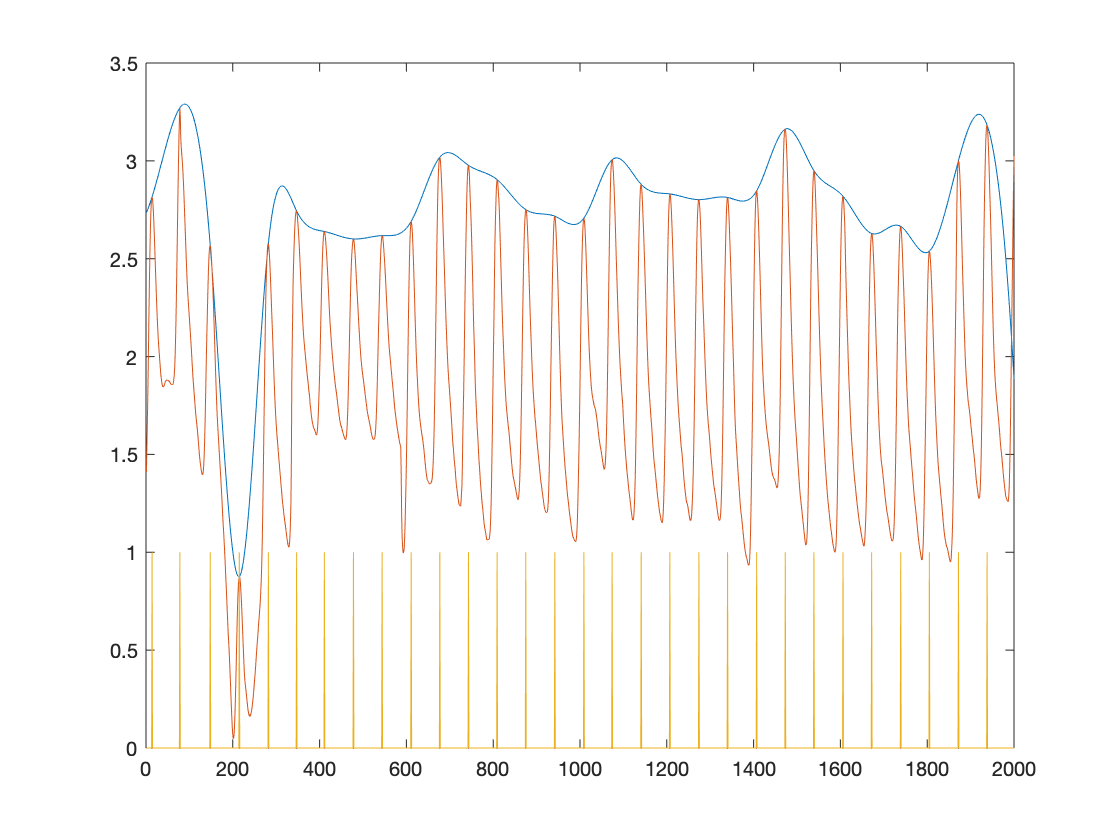


signal = data(:,2:3);
tm = data(:,1);

start_disp = 1;%round(length(tm)/4);
end_disp = 2000;%start_disp+3*Fs;
env = envelope(signal(start_disp:end_disp,2),60,'peak');
clf
plot(env )
hold on
plot(signal(start_disp:end_disp,2))
plot(env == signal(start_disp:end_disp,2))